In order to determine the parameters that describe the more accuretely the bone interface, we are going to compare them to two bone with different caracteristics 

The following table sum up the different parameters : 

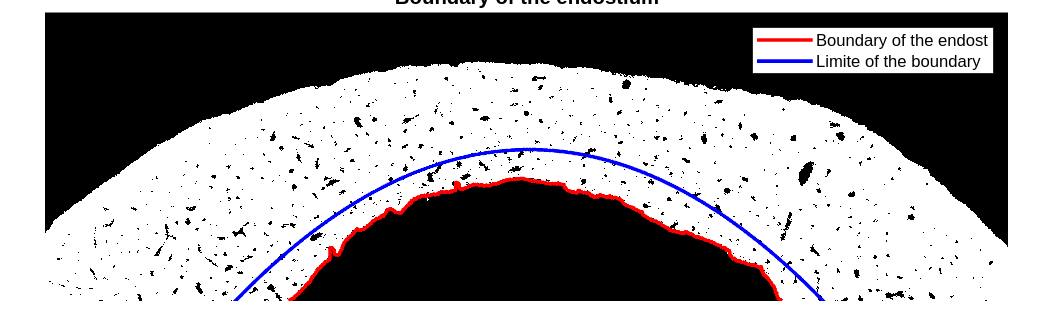

The bone as a porosity of 5.7 % in a width of 0.5 wavelength before the endost thus 0.70 mm
 22.5 % of the pores are concentrated in the width of 0.5 wavelength before the endost

bone = '227G';
num_slice = 1590;
DisplayPorosity(bone, num_slice)

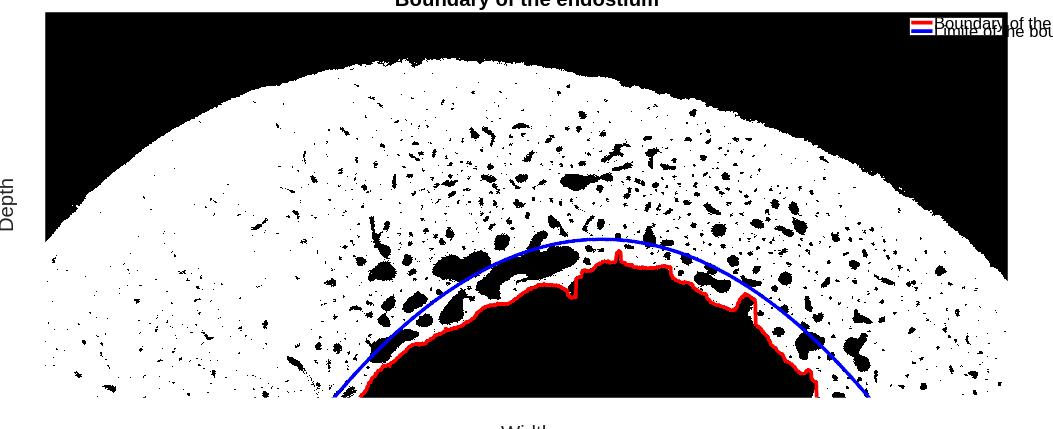

The bone as a porosity of 34.4 % in a width of 0.5 wavelength before the endost thus 0.70 mm
 42.1 % of the pores are concentrated in the width of 0.8 wavelength before the endost

bone = '245D';
num_slice = 800;
DisplayPorosity(bone, num_slice)

function [] = DisplayPorosity(bone, num_slice)
    dirname = ['/calculSSD//Dossier partagé image os exvivo/', bone, '/'];
    file = ['SAMPLE_', bone, '_SLICE_', sprintf('%04d', num_slice), '.bmp']; 
    filename = fullfile(dirname, file);
    
    bone_bmp = imread(filename); 
    threshold = graythresh(bone_bmp); % Find an automatic threshold
    binaryImage = imbinarize(bone_bmp, threshold);
    
    %% Compute the porosity of the bone
    % Compute X-Ray image and ultrasound rf informations 
    [boundaryEndost, ~] = ExtractBoundary(filename, false);
    
    % Compute the porosity in a surface of one wavelength around the boundary
    nbWavelength = 0.75;
    [porosity, totalVolume] = ComputePorosity(binaryImage, boundaryEndost, nbWavelength, true);

    filledImage = imfill(binaryImage, 'holes');
    concentrationEndost = porosity*totalVolume/(sum(filledImage, 'all') - sum(binaryImage, 'all'));

    fprintf('\n %.1f %% of the pores are concentrated in the width of %.1f wavelength before the endost', ...
            concentrationEndost, nbWavelength);
end